addpath("C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\import_data")
warning('off','all')

figure;
AoA = 6

AoA = 6

M = [0.70 0.75 0.80 0.85 0.90 0.95 1.00 1.10 1.20]

M =     0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.1000    1.2000




colorbank = {[128, 0, 255]/256 [0, 32, 255]/256 [0, 128, 255]/256 [0, 255, 255]/256 [0, 255, 0]/256 [255, 191, 0]/256 [255, 128, 0]/256 [255, 0, 0]/256 [255, 0, 191]/256};
markerbank = {'o' '^' 'd'};
markersize = 3; markerindices = 5:20:1000; markerfacecolor = 'w'; linewidth = 0.8;

AeroData = cell(length(AoA),length(M));
DragLines = gobjects(size(AeroData));
LegendLabels = string(size(AeroData));

for ind_AoA=1:length(AoA)
    for ind_M=1:length(M)
        AeroData{ind_AoA,ind_M} = importAeroData(AoA(ind_AoA), M(ind_M));
        DragLines(ind_AoA,ind_M) = line(AeroData{ind_AoA,ind_M}.Time, AeroData{ind_AoA,ind_M}.DragCoef);
        DragLines(ind_AoA,ind_M).Marker = markerbank{ind_AoA};
        DragLines(ind_AoA,ind_M).MarkerSize = markersize;
        DragLines(ind_AoA,ind_M).MarkerIndices = markerindices;
        DragLines(ind_AoA,ind_M).MarkerFaceColor = markerfacecolor;
        DragLines(ind_AoA,ind_M).LineWidth = linewidth;
        DragLines(ind_AoA,ind_M).Color = colorbank{ind_M};
        LegendLabels(ind_AoA,ind_M) = "\alpha=" + AeroData{ind_AoA,ind_M}.AoA + "°, M=" + AeroData{ind_AoA,ind_M}.MachNumber;
    end
end


AvgDragLines = gobjects(size(AeroData));

for ind_AoA=1:length(AoA)
    for ind_M=1:length(M)
        AvgDragLines(ind_AoA,ind_M) = yline(AeroData{ind_AoA,ind_M}.AvgDragCoef);
        AvgDragLines(ind_AoA,ind_M).LineWidth = linewidth*1.5;
        AvgDragLines(ind_AoA,ind_M).LineStyle = '--';        
        AvgDragLines(ind_AoA,ind_M).Color = colorbank{ind_M};
    end
end

xlim([0,0.1])
xlabel("Time [s]",FontSize=11)
%ylim([0,0.09])
ylabel("C_D",FontSize=13)

legend(LegendLabels,Location="southoutside",NumColumns=3)
figposition = [10,10,600,600];
set(gcf,"Position",figposition);
set(gca,'FontName','Times');

filenamestring="C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\plot_aero_data\graphs\DragCoef-Graph-" + num2str(AoA) + "deg.png"

filenamestring = "C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\plot_data\graphs\DragCoef-Graph-6deg.png"

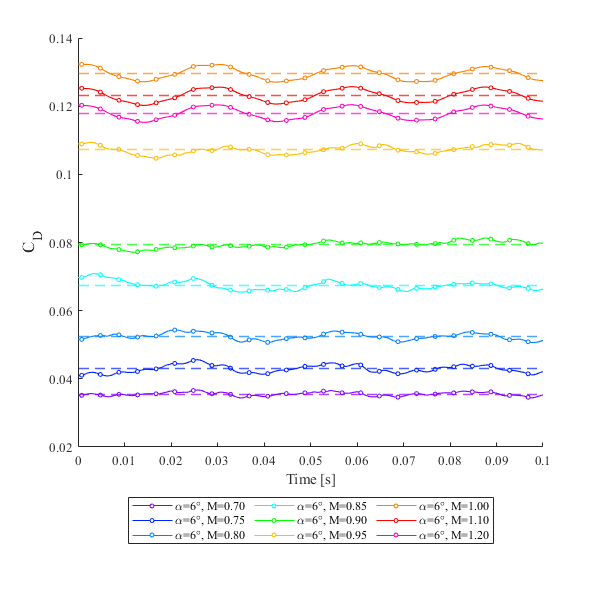

exportgraphics(gcf,filenamestring,"Resolution",300)